`3. ``调用信号产生函数``xtg（见教材P295）产生具有加性噪声的信号xt，显示xt波形及其频谱。设计一FIR 数字低通滤波器，从高频噪声中提取xt中的单频调幅信号，要求信号幅频失真小于0.1dB,噪声频谱衰减不小于60dB。`

`（``1）观察xt的频谱，确定滤波器指标参数。`

`（``2）根据滤波器指标选择合适的窗函数，计算窗函数的长度N，设计一个FIR低通滤波器，绘图显示滤波器的频响特性曲线`

`（3）用设计的FIR低通滤波器对xt进行滤波，绘图显示滤波器输出信号的时域和频域波形图`

绘制x(t) 与 X(w)

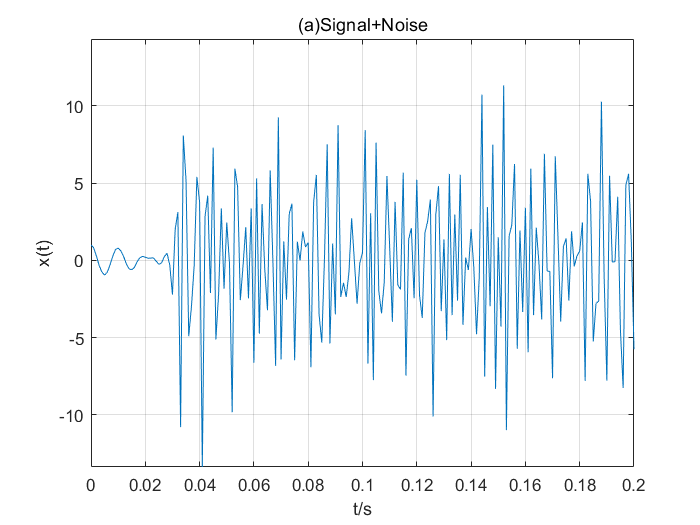

%===========绘制x(t) 与 X(w)============
Fs = 1000; T = 1/Fs; N = 1000; Tp = N * T;
xt = xtg(Fs, N);
t=0:T:(N-1)*T;
fst=fft(xt,N);k=0:N-1;f=k/Tp;

plot(t,xt);
grid;xlabel('t/s');ylabel('x(t)');
axis([0,Tp/5,min(xt),max(xt)]);title('(a)Signal+Noise');

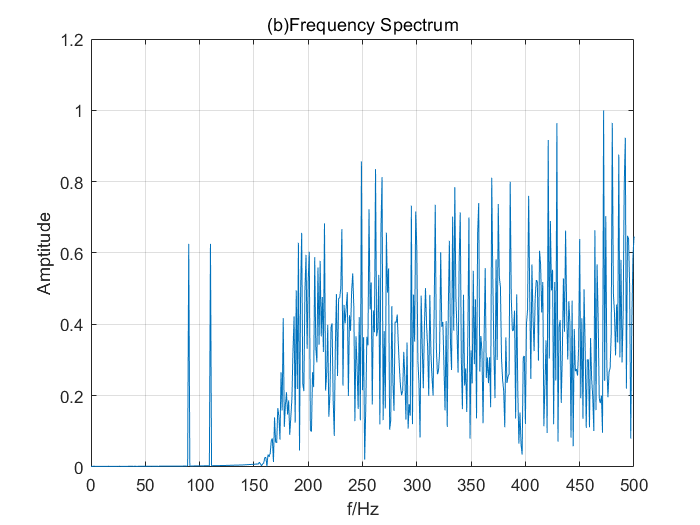


plot(f,abs(fst)/max(abs(fst)));grid;title('(b)Frequency Spectrum')
axis([0,Fs/2,0,1.2]);
xlabel('f/Hz');ylabel('Amptitude');

x(t) 的频谱在右侧应该有 f_0 + f_c 和 f_c - f_0 的两项频率冲激, 因此上限截止频率为f_0 + f_c = 110Hz 因此通带截止频率至少>=110Hz 

观察频谱, 根据提示③, 选取以下参数:

通带截止频率fp = 120Hz

阻带截止频率fs = 150Hz

wp = 0.24 pi

ws = 0.3 pi

rp = 0.1 dB

rs = 60dB

接着设计fir数字滤波器

**由于最大衰减要在 60dB , 因此选用 Blackman 窗**

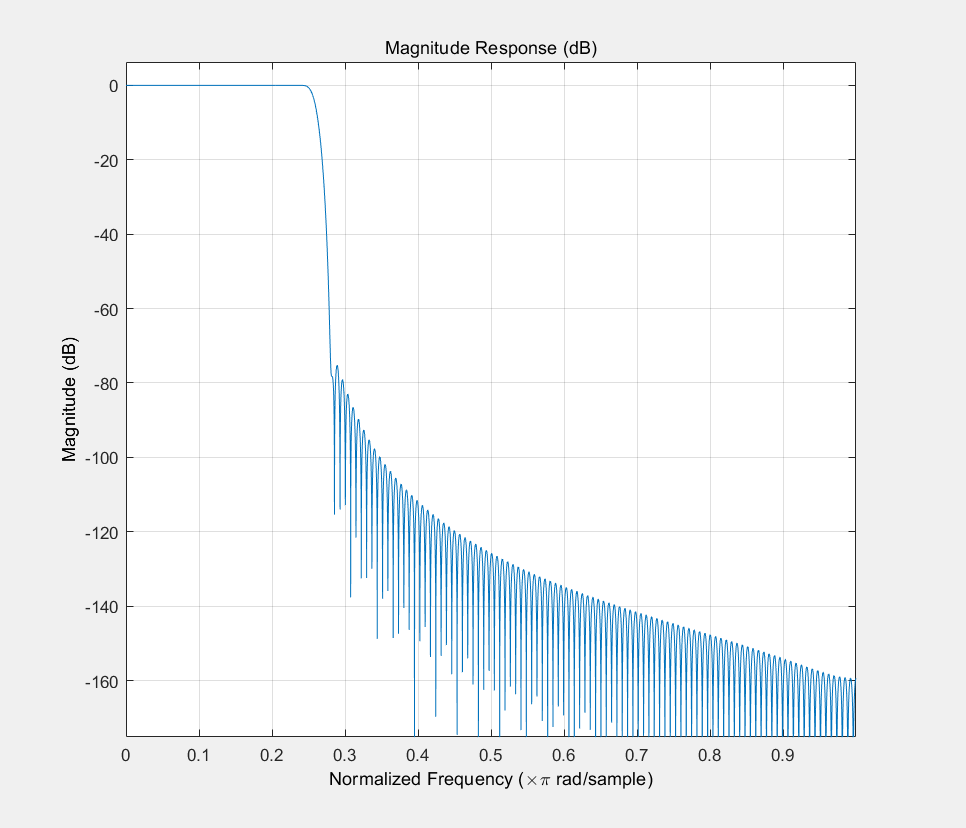

fp = 120;  fs = 140; 
wp = 2*pi*fp/Fs;ws = 2*pi*fs/Fs;
rp = 0.1;rs = 60;

wc = (wp+ws)/2;  % 确定截止频率
B =  ws - wp;   % 确定过渡带宽度

N0 = ceil(11*pi/B);   % 根据表7.2.2 确定N
hbn1 = fir1(N0-1, wc/pi, 'low',blackman(N0));   % 归一化 wc 确定 冲激响应参数

fvtool(hbn1);  % 绘制滤波器图像

观察滤波器图像,发现最大衰减 < 60 dB未满足设计要求, 减小ws, 再次尝试

发现满足要求

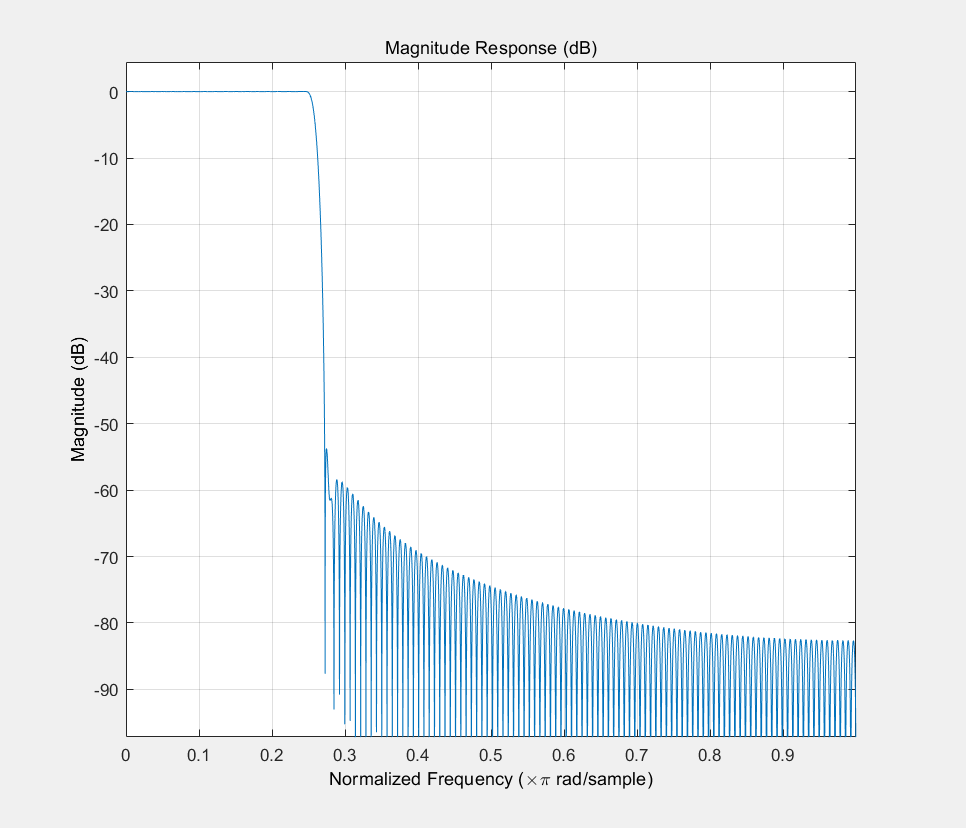

fp = 120;  fs = 140; 
wp = 2*pi*fp/Fs;ws = 2*pi*fs/Fs;


wc = (wp+ws)/2;  % 确定截止频率
B =  ws - wp;   % 确定过渡带宽度

N0 = ceil(11*pi/B);   % 根据表7.2.2 确定N
hbn = fir1(N0, wc/pi);   % 归一化 wc 确定 P冲激响应参数

fvtool(hbn);  % 绘制滤波器图像

`（3）用设计的FIR低通滤波器对xt进行滤波，绘图显示滤波器输出信号的时域和频域波形图`

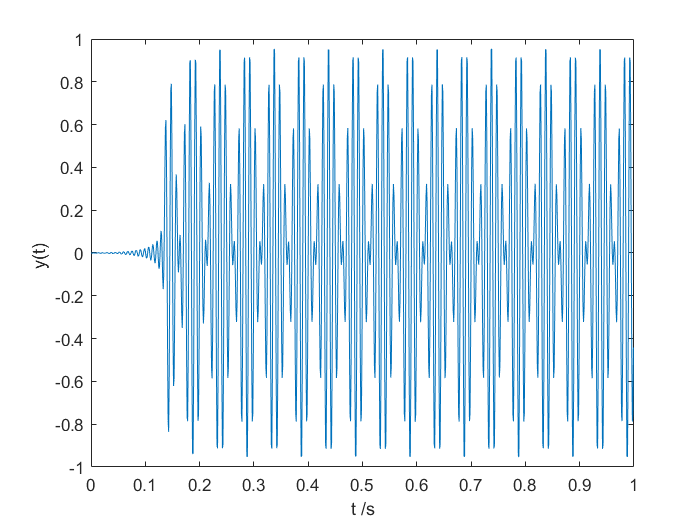


yn = fftfilt(hbn, xt);
% ==========时域波形图==========
plot(t , yn);  
xlabel("t /s");
ylabel("y(t) ");

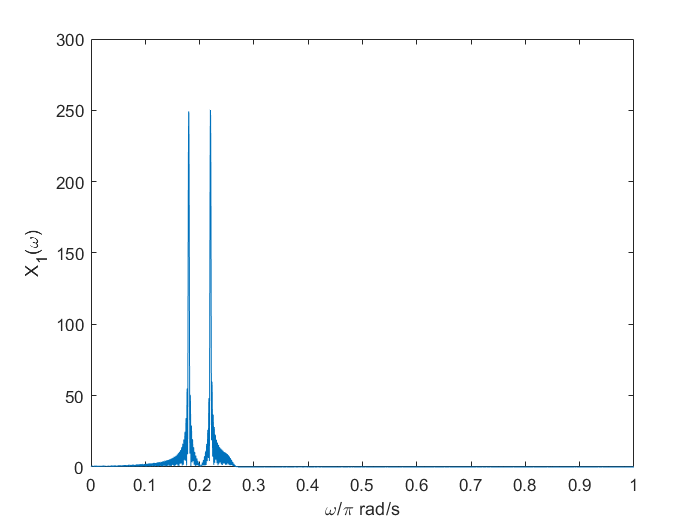


% ==========频域波形图==========
% 时域卷积频域乘积
w = [0:0.001:pi];
Xw = dtft(xt , w);
Hw = dtft(hbn , w);
Yw = Xw.*Hw;

plot(w/pi, abs(Yw)); % yn频谱图
xlabel("\omega/\pi rad/s")
ylabel("X_1(\omega)")

`可以看到幅度基本未改变, 设计完成`